% This script is provided to you. You can use it to generate your own tracking scenario 
% and apply the n-object trackers you have implemented. Try to compare the estimation 
% performance of different trackers, from simple scenario with linear motion/measurement 
% model, high object detection probability and low clutter rate to more complex scenario 
% with nonlinear motion/measurement model, low detection probability and high clutter 
% rate. In complex scenarios, it should be easy to verify that, on average, the n-object
% tracker using multiple hypothesis solutions has the best performance. You can also 
% generate your own groundtruth data. How do the different trackers behave when multiple 
% objects move in close proximity? What do you observe? We also encourage you to tune the 
% different model parameters and observe how they affact the tracking performance. You 
% might also be interested in writting your own plotting function to illustrate the 
% estimation uncertainty of the object state and study how it changes over time. 

clear; close all; clc
dbstop if error

%Choose object detection probability
P_D = 0.9;
%Choose clutter rate
lambda_c = 10;

%Choose linear or nonlinear scenario
scenario_type = 'nonlinear';

%Create tracking scenario
switch(scenario_type)
    case 'linear'
        %Creat sensor model
        range_c = [-1000 1000;-1000 1000];
        sensor_model = modelgen.sensormodel(P_D,lambda_c,range_c);
        
        %Creat linear motion model
        T = 1;
        sigma_q = 5;
        motion_model = motionmodel.cvmodel(T,sigma_q);
        
        %Create linear measurement model
        sigma_r = 10;
        meas_model = measmodel.cvmeasmodel(sigma_r);
        
        %Creat ground truth model
        nbirths = 5;
        K = 100;
        tbirth = zeros(nbirths,1);
        tdeath = zeros(nbirths,1);
        
        initial_state = repmat(struct('x',[],'P',eye(motion_model.d)),[1,nbirths]);
        
        initial_state(1).x = [0; 0; 0; -10];        tbirth(1) = 1;   tdeath(1) = K;
        initial_state(2).x = [400; -600; -10; 5];   tbirth(2) = 1;   tdeath(2) = K;
        initial_state(3).x = [-800; -200; 20; -5];  tbirth(3) = 1;   tdeath(3) = K;
        initial_state(4).x = [0; 0; 7.5; -5];       tbirth(4) = 1;   tdeath(4) = K;
        initial_state(5).x = [-200; 800; -3; -15];  tbirth(5) = 1;   tdeath(5) = K;
          
    case 'nonlinear'
        %Create sensor model
        %Range/bearing measurement range
        range_c = [-1000 1000;-pi pi];
        sensor_model = modelgen.sensormodel(P_D,lambda_c,range_c);
        
        %Create nonlinear motion model (coordinate turn)
        T = 1;
        sigmaV = 1;
        sigmaOmega = pi/180;
        motion_model = motionmodel.ctmodel(T,sigmaV,sigmaOmega);
        
        %Create nonlinear measurement model (range/bearing)
        sigma_r = 5;
        sigma_b = pi/180;
        s = [300;400];
        meas_model = measmodel.rangebearingmeasmodel(sigma_r, sigma_b, s);
        
        %Creat ground truth model
        nbirths = 4;
        K = 100;
        
        initial_state = repmat(struct('x',[],'P',diag([1 1 1 1*pi/90 1*pi/90].^2)),[1,nbirths]);
        
        initial_state(1).x = [50; 50; 5; 0; pi/180];       tbirth(1) = 1;   tdeath(1) = K;
        initial_state(2).x = [50; -50; -20; 0; pi/90];    tbirth(2) = 1;   tdeath(2) = K;
        initial_state(3).x = [-50; 50; -10; 0; pi/360];  tbirth(3) = 1;   tdeath(3) = K;
        initial_state(4).x = [-50; -50; 8; 0; pi/270];   tbirth(4) = 1;   tdeath(4) = K;
end

%Generate true object data (noisy or noiseless) and measurement data
ground_truth = modelgen.groundtruth(nbirths,[initial_state.x],tbirth,tdeath,K);
ifnoisy = 0;
objectdata = objectdatagen(ground_truth,motion_model,ifnoisy);
measdata = measdatagen(objectdata,sensor_model,meas_model);

%N-object tracker parameter setting
P_G = 0.999;            %gating size in percentage
w_min = 1e-3;           %hypothesis pruning threshold
merging_threshold = 2;  %hypothesis merging threshold
M = 100;                %maximum number of hypotheses kept in MHT
density_class_handle = feval(@GaussianDensity);    %density class handle
tracker = n_objectracker();
tracker = tracker.initialize(density_class_handle,P_G,meas_model.d,w_min,merging_threshold,M);

%GNN filter
% GNNestimates = GNNfilter(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);
% GNN_RMSE = RMSE_n_objects(objectdata.X,GNNestimates);

%JPDA filter
% JPDAestimates = JPDAfilter(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);
% JPDA_RMSE = RMSE_n_objects(objectdata.X,JPDAestimates);

%Multi-hypothesis tracker
TOMHTestimates = TOMHT(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);
TOMHT_RMSE = RMSE_n_objects(objectdata.X,TOMHTestimates);

X = sprintf('Root mean square error: MHT: %.3f.',TOMHT_RMSE);
disp(X)

Root mean square error: MHT: 9.183.


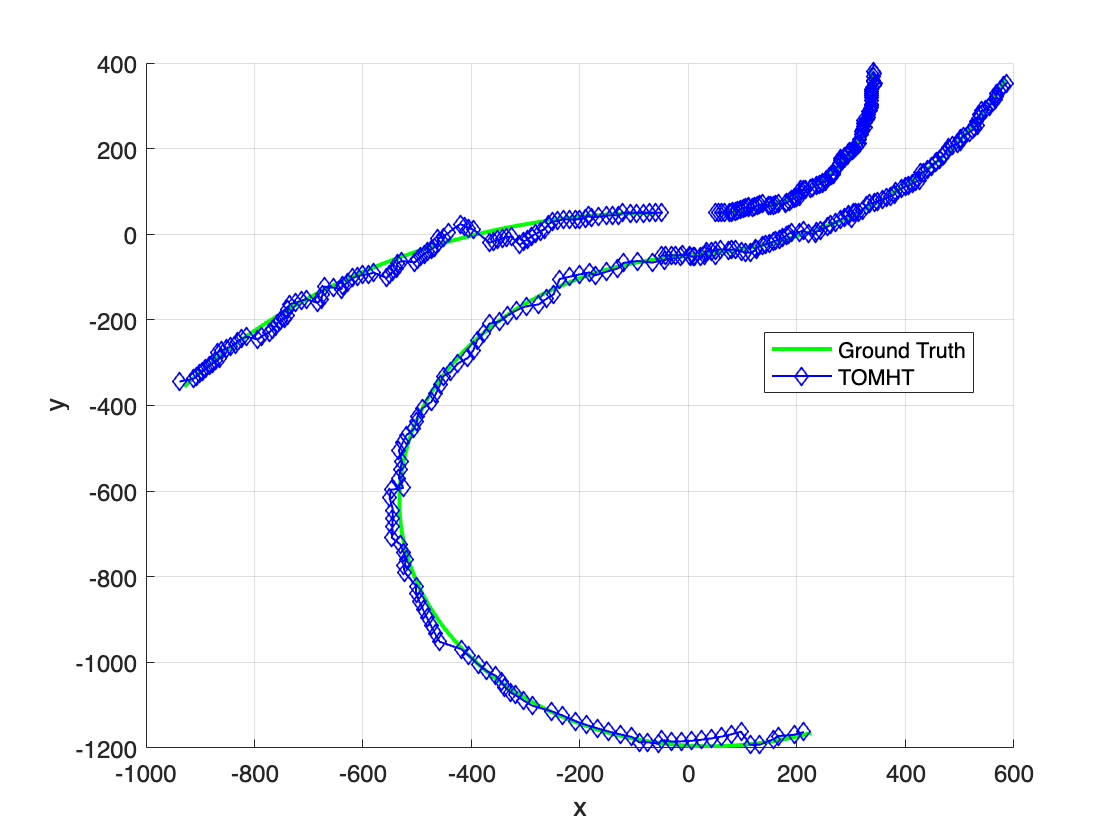

%Ploting
figure
hold on
grid on

for i = 1:nbirths
    h1 = plot(cell2mat(cellfun(@(x) x(1,i), objectdata.X, 'UniformOutput', false)), ...
        cell2mat(cellfun(@(x) x(2,i), objectdata.X, 'UniformOutput', false)), 'g', 'Linewidth', 2);
    h4 = plot(cell2mat(cellfun(@(x) x(1,i), TOMHTestimates, 'UniformOutput', false)), ...
        cell2mat(cellfun(@(x) x(2,i), TOMHTestimates, 'UniformOutput', false)), 'b-d', 'Linewidth', 1);
end

xlabel('x'); ylabel('y')

legend([h1 h4],'Ground Truth','TOMHT', 'Location', 'best')

set(gca,'FontSize',12) 